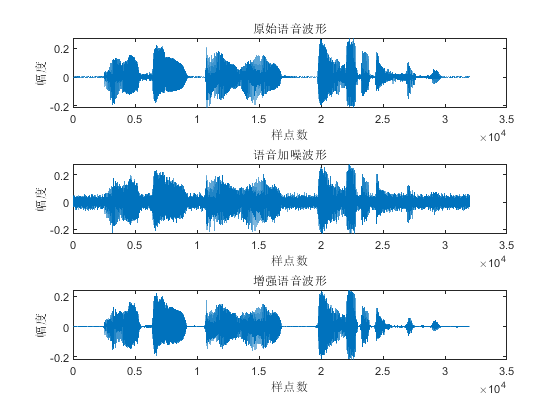

clear; close all;
[speech,fs,nbits]=wavread('bluesky1.wav');% 读入数据
alpha=0.02;             % 噪声水平
winsize=256;            % 窗长
size=length(speech);    % 语音长度
numofwin=floor(size/winsize);   % 帧数
hamwin=zeros(1,size);   % 定义汉明窗长度
enhanced=zeros(1,size); % 定义增强语音的长度
ham=hamming(winsize)';  % 产生汉明窗
x=speech'+alpha*randn(1,size);  % 信号加噪声
% noisy=alpha*randn(1,winsize);   % 噪声估计
% N=fft(noisy);
% nmag=abs(N);            % 噪声功率谱
noisy1=x(1,1:256);
noisy2=x(1,257:512);
noisy3=x(1,513:768);
noisy4=x(1,769:1024);
N=abs(fft(noisy1)).^2+abs(fft(noisy2)).^2+abs(fft(noisy3)).^2+abs(fft(noisy4)).^2;
nmag=0.25*N;
a=5;b=0.0001;
%D=sum(mag(1:10))/10;
% 分帧
for q=1:2*numofwin-1
    frame=x(1+(q-1)*winsize/2:winsize+(q-1)*winsize/2); % 对带噪语音帧间重叠一半取值
    hamwin(1+(q-1)*winsize/2:winsize+(q-1)*winsize/2)=...
        hamwin(1+(q-1)*winsize/2:winsize+(q-1)*winsize/2)+ham;% 加窗
    y=fft(frame.*ham);
    mag=abs(y);     % 带噪语音功率谱
    phase=angle(y); % 带噪语音相位
    % 幅度谱减
    for i=1:winsize
        if mag(i)^2-a*nmag(i)>=0
            clean(i)=mag(i)^2-a*nmag(i);
        else 
            clean(i)=b*mag(i);
        end
    end
    % 频域中重新合成语音
    spectral=(clean.^0.5).*exp(1i*phase);
    % 反傅里叶变换并重叠相加
    enhanced(1+(q-1)*winsize/2:winsize+(q-1)*winsize/2)=...
        enhanced(1+(q-1)*winsize/2:winsize+(q-1)*winsize/2)+real(ifft(spectral));
end
figure(1);
subplot(3,1,1);plot(speech);xlabel('样点数');ylabel('幅度');title('原始语音波形');
subplot(3,1,2);plot(x);xlabel('样点数');ylabel('幅度');title('语音加噪波形');
subplot(3,1,3);plot(enhanced);xlabel('样点数');ylabel('幅度');title('增强语音波形');

audiowrite('bluesky2.wav',enhanced,8000);
